# Algoritmo_di_Bisezione

***Data una generica funzione f(x) in un intervallo [a ,b]. L'algoritmo di bisezione calcola il punto in cui f(x)=0.***

## Sintassi ed Esempi di utilizzo

- `x = algoritmo_di_bisezione(f,x0)` restituisce il valore dell'approssimazione dello zero nell'intervallo specificato x0=[a b].

#### Problema 

Calcolare lo zero  di $2-e^{-x} \;-\sqrt{x}$ nell'intervallo $\left\lbrack 0,4\right\rbrack$.

- `Command Line Matlab`

f =  @(x) 2-exp(-x)-sqrt(x); % funzione handle
x0 = [0 4]; % intervallo iniziale
x= algoritmo_di_bisezione(f,x0);

x

x =      3.921117013138087e+00


`Esecuzione da interfaccia grafica`

 MainGUI();

- `x = algoritmo_di_bisezione(f,x0,TOL)` l'accuratezza della soluzione è determinata dal valore **TOL**, se omesso TOL=eps.

Valore di accuratezza TOL= ${10}^{-10}$

`Command Line Matlab`

f =  @(x) 2-exp(-x)-sqrt(x); % funzione handle
x0 = [0 4]; % intervallo iniziale
x= algoritmo_di_bisezione(f,x0,10^-10);
x

x =      3.921117013203911e+00


-  `x = algoritmo_di_bisezione(f,x0,TOL,NMAX)`  l'accuratezza della soluzione è determinata dal valore **TOL** e `NMAX` rappresenta il numero massimo di iterazioni eseguibili. Se omessi `TOL=eps, NMAX=500`.

Numero massimo di iterazioni inserito NMAX=$100$

` Command Line Matlab`

f =  @(x) 2-exp(-x)-sqrt(x); % funzione handle
x0 = [0 4]; % intervallo iniziale
x= algoritmo_di_bisezione(f,x0,10^-10,100);
x

x =      3.921117013203911e+00


-  `[x uscita] = algoritmo_di_bisezione(f,x0,_,_)` restituisce, oltre al valore dell'approssimazione, una struttura *uscita *contenente: `fx `il valore che assume la funzione nel punto x  , `numiter` rappresentante il numero di iterazioni effettuate dell'algoritmo.

`Esempio da Command Line Matlab`

f =  @(x) 2-exp(-x)-sqrt(x); % funzione handle
x0 = [0 4]; % intervallo iniziale
[x,uscita]= algoritmo_di_bisezione(f,x0,10^-10,100);
x

x =      3.921117013203911e+00


uscita.fx

ans =     -1.531641480312373e-11


uscita.numiter

ans =     34


-  `[x uscita graf] = algoritmo_di_bisezione(f,x0,_,_)` ritorna  una variabile di tipo  `char `rappresentante il grafico della funzione e dell'approssimazione a zero determinata.

`Esecuzione da interfaccia grafica`

 MainGUI();

`Esempio da Command Line Matlab`

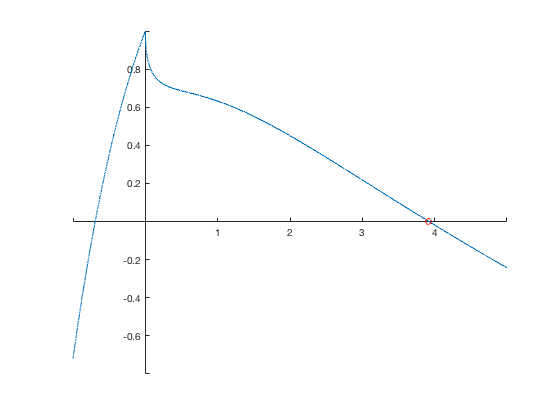

f =  @(x) 2-exp(-x)-sqrt(x); % funzione handle
x0 = [0 4]; % intervallo iniziale
[x,uscita,graf]= algoritmo_di_bisezione(f,x0,10^-10,100);

x(1)

ans =      3.921117013203911e+00


uscita.fx

ans =     -1.531641480312373e-11


uscita.numiter

ans =     34


graf;

## Ulteriori informazioni: 

 doc  algoritmo_di_bisezione
 MainGUI();%Interfaccia grafica che risolve il problema della ricerca dello zero
%a partire dall'input utente. Sono presenti casi di test e documentazioni
%dettagliate.

## Autori

` Giuseppe Napolano M63000856 Raffaele Formisano M63000912 Giuseppe Romito M63000936`